Load data

load('MobileSensorData/steps-6-280.mat');
lat=Position.latitude;
lon=Position.longitude;
positionDatetime=Position.Timestamp;

Xacc = Acceleration.X;
Yacc = Acceleration.Y;
Zacc = Acceleration.Z;
accelDatetime=Acceleration.Timestamp;


positionTime=timeElapsed(positionDatetime);
accelTime=timeElapsed(accelDatetime);
spd = Position.speed

spd =     0.1900
    0.7600
    1.2500
    1.0200
    1.1900
    1.1800
    1.0800
    1.0100
    1.0700
    1.0900


Calculate distance

distanceInMeters = getDistance(lat,lon)

distanceInMeters = 209.2681


stride = 0.7

stride = 0.7000


steps = distanceInMeters / stride

steps = 298.9544

**Plot speed**

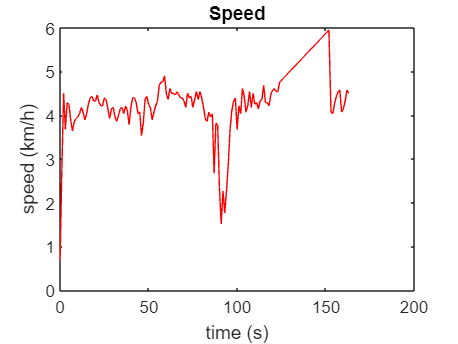

plot(positionTime, Position.speed*3.6, "r")
title("Speed")
xlabel("time (s)")
ylabel("speed (km/h)")

**Create map image**

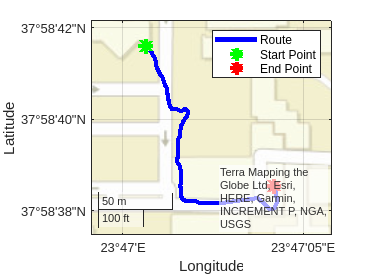

geoplot(lat(2:end-1), lon(2:end-1),'-b',lat(1), lon(1),'*g',lat(end), lon(end),'*r','LineWidth',3, 'MarkerSize',10 )
legend("Route","Start Point","End Point");

minlat = min(lat)-0.0001;
minlon = min(lon)-0.0001;
maxlat = max(lat)+0.0001;
maxlon = max(lon)+0.0001;

geolimits([minlat maxlat], [minlon maxlon])
geobasemap streets

**Color speed map**

nBins = 10;

binSpacing = (max(spd) - min(spd))/nBins; 
binRanges = min(spd):binSpacing:max(spd)-binSpacing; 

binRanges(end+1) = inf;

[~, spdBins] = histc(spd, binRanges);

lat = lat';
lon = lon';
spdBins = spdBins';

s = geoshape();

for k = 1:nBins
    
    latValid = nan(1, length(lat));
    latValid(spdBins==k) = lat(spdBins==k);
    
    lonValid = nan(1, length(lon));
    lonValid(spdBins==k) = lon(spdBins==k);    

    transitions = [diff(spdBins) 0];
    insertionInd = find(spdBins==k & transitions~=0) + 1;

    latSeg = zeros(1, length(latValid) + length(insertionInd));
    latSeg(insertionInd + (0:length(insertionInd)-1)) = lat(insertionInd);
    latSeg(~latSeg) = latValid;
    
    lonSeg = zeros(1, length(lonValid) + length(insertionInd));
    lonSeg(insertionInd + (0:length(insertionInd)-1)) = lon(insertionInd);
    lonSeg(~lonSeg) = lonValid;

    s(k) = geoshape(latSeg, lonSeg);
    
end

Create the web map

wm = webmap('Open Street Map');

colors = autumn(nBins);

wmline(s, 'Color', colors, 'Width', 5);

wmzoom(18);
